# EE-414 Speech Processing Lab

#  Lab-9

## Introduction:

We know that speech signals are basically generated by convolving the excitation source component and the vocal tract system component. We need to know the information of these components individually to do proper analysis, so deconvolution needs to be done inorder to do so. In the previous lab, we did cepstral analysis, where we got the components individually in the frequency domain. In this lab, we will learn about linear prediction analysis which allows us to find these components in the time domain itself.

## Aim 

#### ● To compute LP coefficients and LP residual of a given speech signal. 

#### ● To compute the formant parameters by LP analysis. 

#### ● To compute the excitation parameters like pitch by LP analysis. 

#### ● To compute the normalized error curves for voiced and unvoiced segments of speech. 

Spectrogram and Waveform of "Speech Signal" from wavesurfer

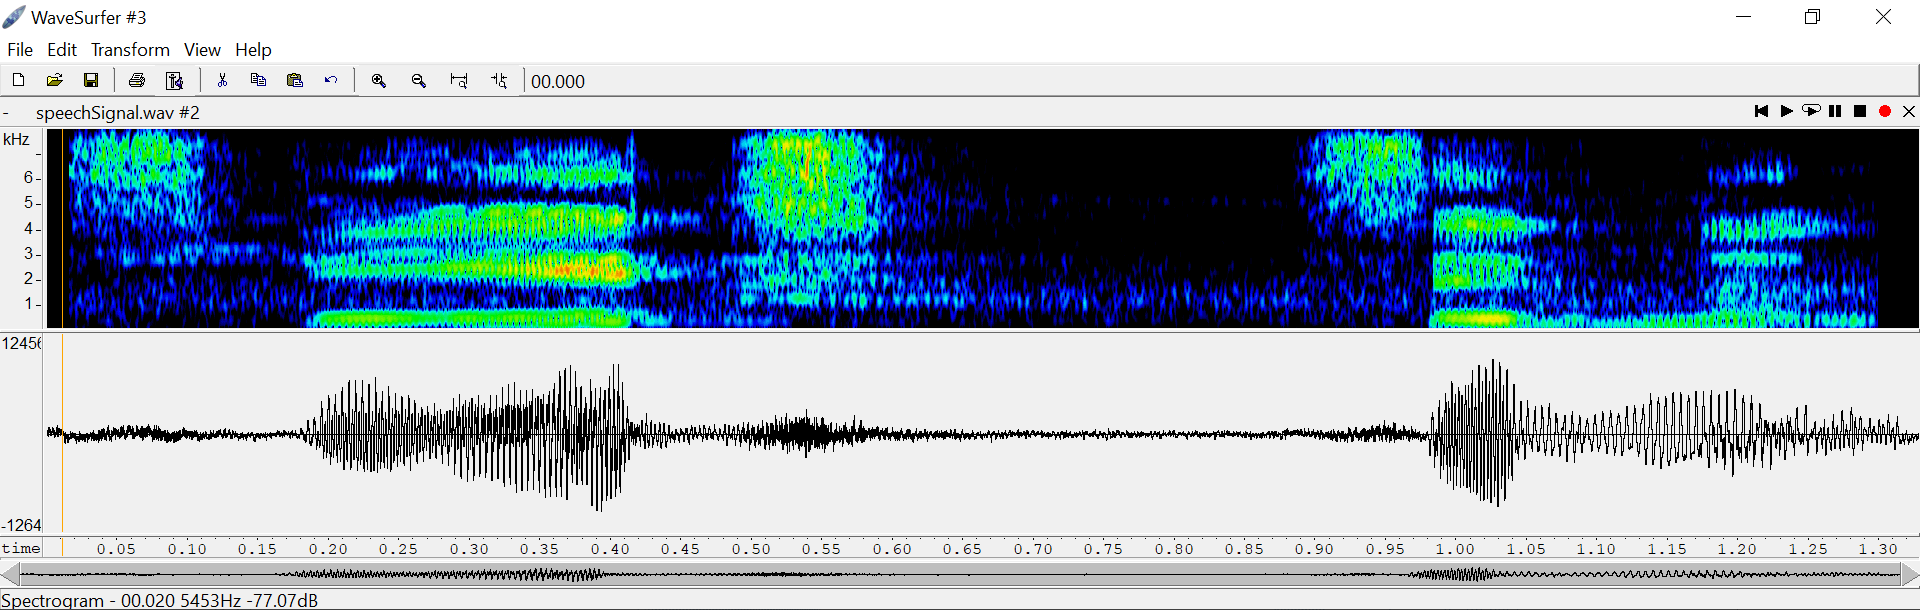

Record (16kHz, 16bit) the word “speech signal”; truncate long silence regions. 

### A. Estimating Linear Prediction (LP) coefficients from the speech.

a. Select a frame (25 ms long) at the center of a voiced segment. Estimate the LPCs of the segment using the autocorrelation method. 

#### Theory:

The prediction of current sample as a linear combination of past *p* samples form the basis of linear prediction analysis where *p* is the order of prediction. The predicted sample s^(n) can be represented as follows,

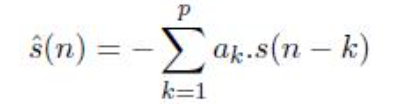

where a_k is the linear prediction coefficients and s(n) is the windowed speech sequence.

The prediction error e(n) is computed by the difference between actual sample s(n) and the predicted sample s^(n) which is given by,

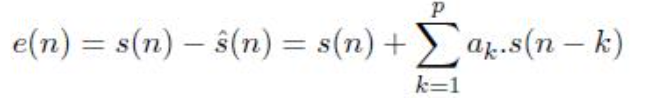

We need to minimise this error, and we find the LP coefficients that minimize this error the best way possible.

We can compute the LP coefficients by using least squares auto-correlation method (which can be done by minimizing the total prediction error).

The total prediction error is given by:

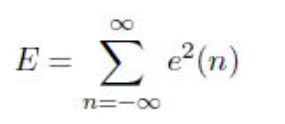                           

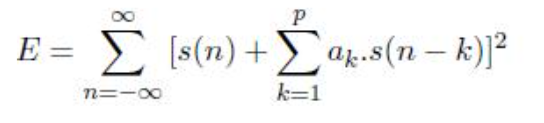

If we differentiate this w.r.t to a_k and equate it to 0, we can find the values of a_k which minimize the total prediction error E. 

i.e.

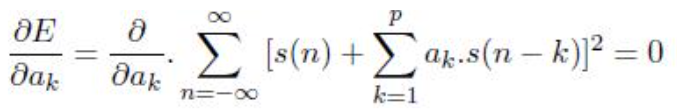

Finally upon further simplification we can write it as:

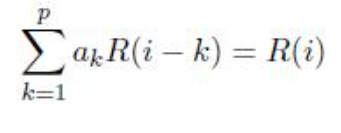

Where R(i) is written as:

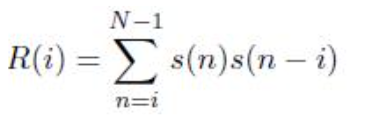

which can be written in matrix form as :

Where 

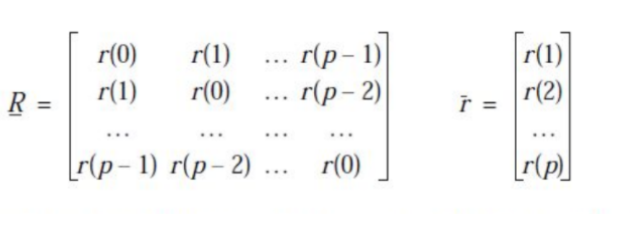

We need to find A, which is the matrix containing the LP coefficients, so we multiply both sides by the inverse matrix of R to get:

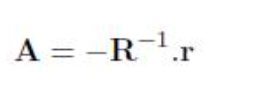

#### Procedure:

We take the sample sound and take the voiced segment of 25 ms. We then plot the waveform and its ACF. Finally we compute the LP coefficients by following the necessary steps as mentioned in the theory part.

#### **Code:**

**a.**

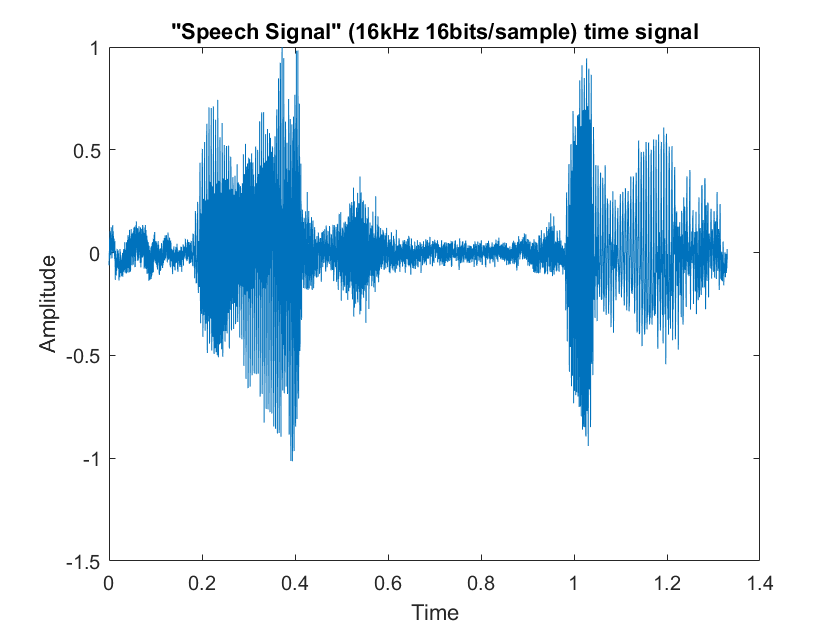

close all; clc; clear all;

[y,fs]=audioread('speechSignal.wav'); 

sound_sample = y(:,1); % Taking left channel
sound_sample = sound_sample./max(sound_sample); % Normalizing

% "Speech Signal" 
plot_time_signal(sound_sample, fs, '"Speech Signal" (16kHz 16bits/sample) time signal'); 

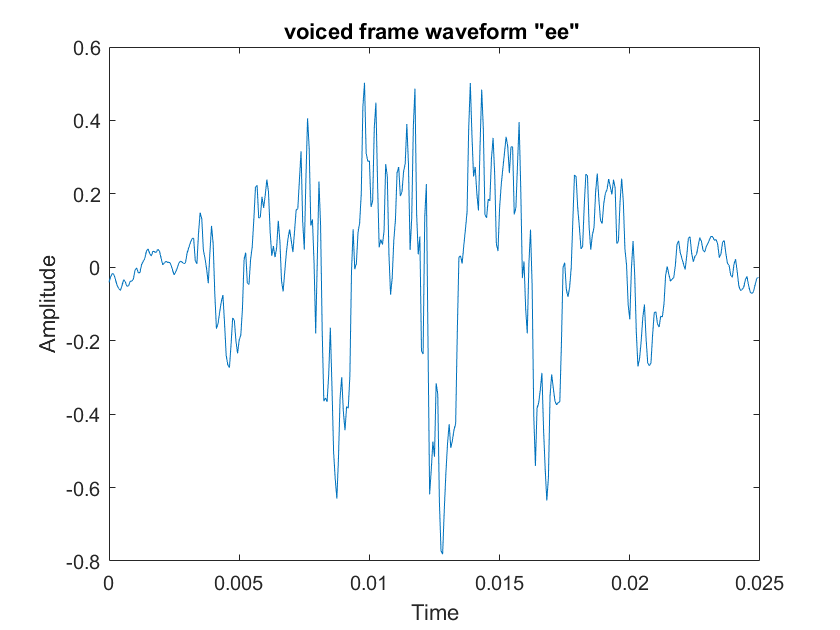

% getting s_n
voiced_part = sound_sample(round(0.30*fs):round(0.40*fs)); % ee 
voiced_frame = voiced_part(round(length(voiced_part)/2) - 0.0125*fs:round(length(voiced_part)/2) + 0.0125*fs - 1);

% getting x_n by windowing
win = dsp.Window("Hamming");
voiced_hamm = win(voiced_frame);

% plotting for voiced frame
plot_time_signal(voiced_hamm, fs, 'voiced frame waveform "ee" ');

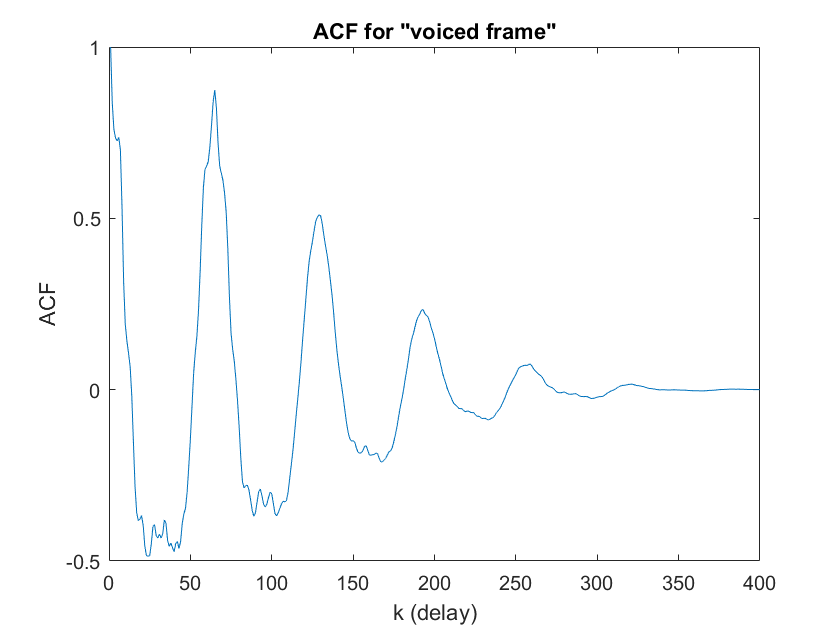

ACF = autocorr(length(voiced_hamm), voiced_hamm);
plot(ACF);
title('ACF for "voiced frame"');
xlabel('k (delay)');
ylabel('ACF');

ACF = autocorr(length(voiced_hamm), voiced_hamm);
P = 13; % Order

R = ACF(1:P); % R(0) to R(P-1)
r = (ACF(2:(P+1)))'; % R(1) to R(P)

R = toeplitz(R); % writing in form of toeplitz matrix
L_coeffs = -(inv(R))*(r)

L_coeffs =    -1.0166
   -0.1554
    0.2832
    0.6029
    0.1616
   -0.3807
   -0.1208
    0.1443
   -0.3657
   -0.6160


#### **Observations:**

We are able to get the LP coefficients.

### B. Computing LP residual 

a. Using the computed LPCs, derive the LP residual signal. 

#### Theory:

LP residual is the prediction error e(n) obtained as the difference between the predicted speech sample s^(n) and the current sample s(n).

In the frequency domain, we get

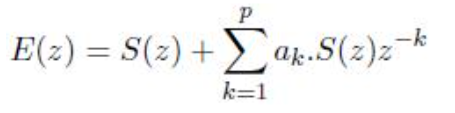

Then, 

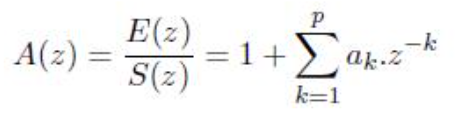

Where A(z) is the LP coefficients in frequency domain.

the LP spectrum H(z) is obtained as follows (by taking reciprocal of A(z)),

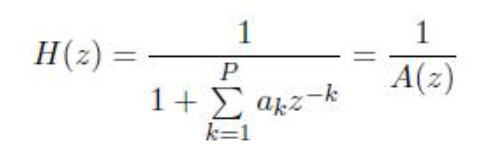

So we obtain LP residual by inverse filtering of speech.

#### Procedure:

We can get the LP residual by simply convolving the voiced speech frame with the LP coefficients we have already found in the previous problem statement. We then compute the ACF of this LP residual and plot it as well.

#### **Code:**

LP_residual = conv(voiced_hamm, L_coeffs);
plot_time_signal(voiced_hamm, fs, 'voiced frame waveform "ee" ');

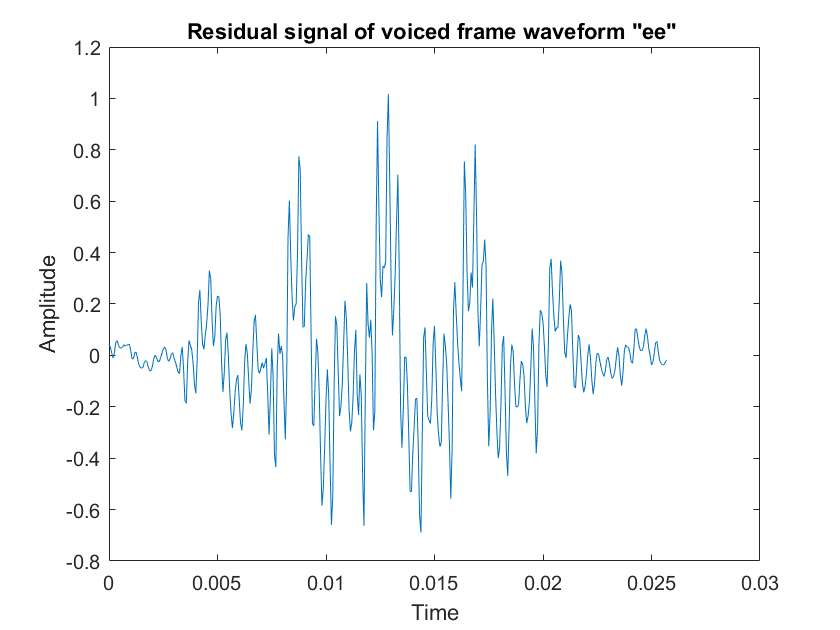

plot_time_signal(LP_residual, fs, 'Residual signal of voiced frame waveform "ee" ');

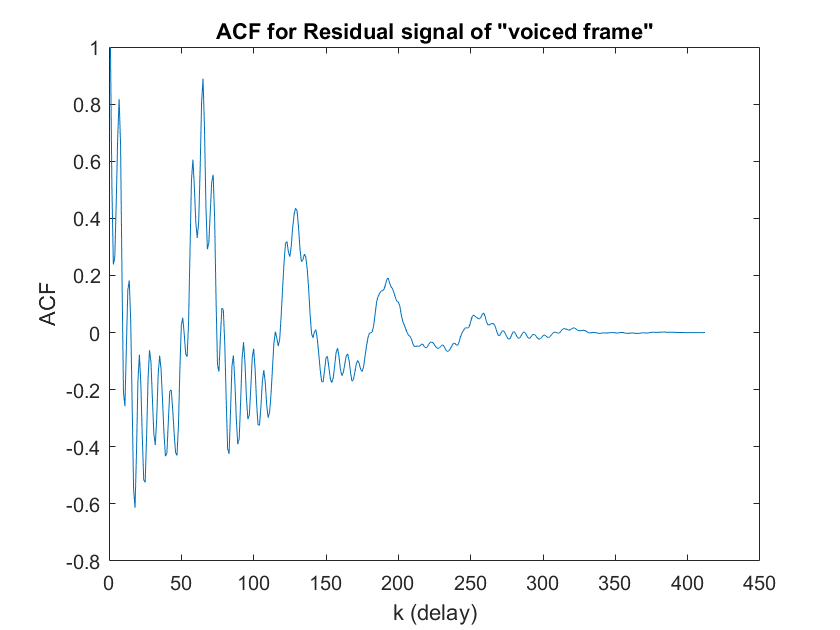

ACF = autocorr(length(LP_residual), LP_residual);
plot(ACF);
title('ACF for Residual signal of "voiced frame"');
xlabel('k (delay)');
ylabel('ACF');

#### Observations:

We are able to get the residual signal, which appears very noisy in nature (as it signifies the error).

### C.  Pitch estimation from LP residual: 

a. Estimate the pitch from the estimated LP residual using autocorrelation. 

#### Theory:

The periodicity of the error (LP residual is an error signal) gives the pitch period of that speech segment and this can be computed by the autocorrelation method. 

#### Procedure:

The pitch period can be found as the time difference between the highest peak and the next highest peak of the auto correlation function.

#### Code:

[mag, k] = max(ACF(2:end)); % ignoring the 1st index as it has highest peak
pitch_pd = k+1;
pitch_f = (1/pitch_pd)*fs;
fprintf("Pitch Frequency: %.3f Hz", pitch_f);

Pitch Frequency: 246.154 Hz

#### **Observations:**

We get pitch frequency as 246.154, which is matching the pitch frequency we estimated from cepstral analysis.

### D.Formant estimation from LP spectrum:

a. Explain, step by step, the procedure of computing the LP spectrum from LPCs. 

b. Demonstrate the same on the voiced frame selected above.

#### Theory:

LP analysis separates speech signal into slowly varying vocal tract component represented by LP filter/spectrum (H(z)) and fast varying excitation component given by the LP residual (e(n)). As the LP spectrum provides the vocaltract characteristics, the vocaltract resonances (formants) can be estimated from the LP spectrum by picking the peaks from the magnitude LP spectrum (|H(z)|).

#### Procedure:

**a) **We can estimate the formant characteristics by taking fourier transform of the reciprocal of LP coefficients, i.e. we can see formant structure by seeing the log magnitude spectrum. We have already found the LP coefficients in the previous problem statement therefore we just need to convert it to the frequency domain by fourier transform and find the peaks present (using a peak picking algorithm) which correspond to the formant frequencies.

#### Code

#### b)

% getting vocal tract system (H_z) component
[L_coeffs, m] = lpc(voiced_frame) 

L_coeffs =     1.0000   -1.1750    0.7815   -0.4823    0.0738   -0.1484   -0.0026   -0.4706    0.2726    0.3897   -0.2088    0.1391    0.1131   -0.1657    0.1817   -0.0022   -0.2240    0.0676    0.0853    0.0313    0.0041   -0.0813    0.0997   -0.0905   -0.0123    0.0746   -0.0941    0.0304   -0.0260    0.0620   -0.0553    0.0547    0.0728   -0.1470    0.0592    0.0738    0.0164    0.0420   -0.0476    0.0132    0.0498   -0.0034   -0.0791    0.0236   -0.0449    0.0867    0.0124   -0.0529    0.0994   -0.0971


m = 0.0048

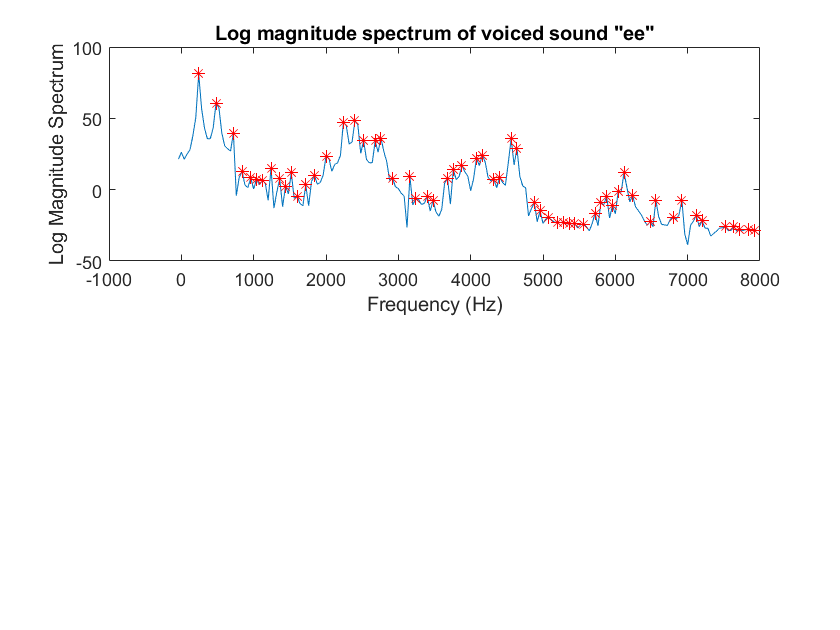

A_z = abs(fftshift(fft(L_coeffs, length(voiced_hamm))));
H_z = 1./A_z;
H_z = 20*log(H_z);
n = length(voiced_hamm);
H_z = H_z(ceil(n/2):end);

formant_freqs_voiced = [];

% peak picking
for l = 2 : length(H_z) - 1
    if H_z(l) > H_z(l-1) && H_z(l) > H_z(l+1)
        formant_freqs_voiced = [formant_freqs_voiced l];
    end
end

formant_freqs_voiced = formant_freqs_voiced(2:end);

% plotting spectrum
f = fs*[-n/2:n/2-1]/n;
f = f(ceil(n/2):end);
subplot(211)
plot(f, H_z);
hold on
plot(f(formant_freqs_voiced),H_z(formant_freqs_voiced),'r*')
xlabel('Frequency (Hz)')
ylabel('Log Magnitude Spectrum');
title('Log magnitude spectrum of voiced sound "ee"');

fprintf("Formant Frequencies: %.d Hz\n", f(formant_freqs_voiced));

Formant Frequencies: 240 Hz
Formant Frequencies: 480 Hz
Formant Frequencies: 720 Hz
Formant Frequencies: 840 Hz
Formant Frequencies: 960 Hz
Formant Frequencies: 1040 Hz
Formant Frequencies: 1120 Hz
Formant Frequencies: 1240 Hz
Formant Frequencies: 1360 Hz
Formant Frequencies: 1440 Hz
Formant Frequencies: 1520 Hz
Formant Frequencies: 1600 Hz
Formant Frequencies: 1720 Hz
Formant Frequencies: 1840 Hz
Formant Frequencies: 2000 Hz
Formant Frequencies: 2240 Hz
Formant Frequencies: 2400 Hz
Formant Frequencies: 2520 Hz
Formant Frequencies: 2680 Hz
Formant Frequencies: 2760 Hz
Formant Frequencies: 2920 Hz
Formant Frequencies: 3160 Hz
Formant Frequencies: 3240 Hz
Formant Frequencies: 3400 Hz
Formant Frequencies: 3480 Hz
Formant Frequencies: 3680 Hz
Formant Frequencies: 3760 Hz
Formant Frequencies: 3880 Hz
Formant Frequencies: 4080 Hz
Formant Frequencies: 4160 Hz
Formant Frequencies: 4320 Hz
Formant Frequencies: 4400 Hz
Formant Frequencies: 4560 Hz
Formant Frequencies: 4640 Hz
Formant Frequencies

#### Observations:

We are able to find the location of the formant frequencies from the LP spectrum. The formant frequencies are mentioned above.

### E.  Normalized Error 

a. Select the 25ms frame at the center of the voiced and unvoiced frame respectively. Compute the normalized LP residual error as a function of the order of LP prediction. Plot normalized error curve against the prediction order for both voiced and unvoiced frames 

b. Comment upon the choice of optimal prediction order for the segments. 

#### Theory:

The normalized error is defined as the ratio of the total minimum error to the total energy of the signal. 

Where Ep is written as follows:

#### 

With the help of normalized error curve we can find the required LP order.

#### Procedure:

We take the voiced and unvoiced part and take a 25ms segment. We then find Vp for different p values and plot it finally.

#### Code:

close hidden
% voiced part
voiced_part = sound_sample(round(0.30*fs):round(0.40*fs)); % ee 
voiced_frame = voiced_part(round(length(voiced_part)/2) - 0.0125*fs:round(length(voiced_part)/2) + 0.0125*fs - 1);

win = dsp.Window("Hamming");
voiced_hamm = win(voiced_frame);

ACF = autocorr(length(voiced_hamm), voiced_hamm);

V_p_voiced = [];
for p = 2:50
    
    R = ACF(1:p); % R(0) to R(P-1)
    r = (ACF(2:(p+1)))'; % R(1) to R(P)

    [l, m] = lpc(voiced_hamm, p);
    R_k = r;
    E_p = R(1) + sum(l(2:end).*R_k');
    V_p_voiced = [V_p_voiced E_p/R(1)];
end
V_p_voiced = V_p_voiced/max(V_p_voiced);

% unvoiced part
unvoiced_part = sound_sample(round(0.5*fs):round(0.6*fs)); % ch
unvoiced_frame = unvoiced_part(round(length(unvoiced_part)/2) - 0.0125*fs:round(length(unvoiced_part)/2) + 0.0125*fs - 1);

win = dsp.Window("Hamming");
unvoiced_hamm = win(unvoiced_frame);

ACF = autocorr(length(unvoiced_hamm), unvoiced_hamm);

V_p_unvoiced = [];
for p = 2:50
    
    R = ACF(1:p); % R(0) to R(P-1)
    r = (ACF(2:(p+1)))'; % R(1) to R(P)
    
    [l, m] = lpc(unvoiced_hamm, p);

    R_k = r;
    E_p = R(1) +  sum(l(2:end).*R_k');
    V_p_unvoiced = [V_p_unvoiced E_p/R(1)];
end
V_p_unvoiced = V_p_unvoiced/max(V_p_unvoiced);


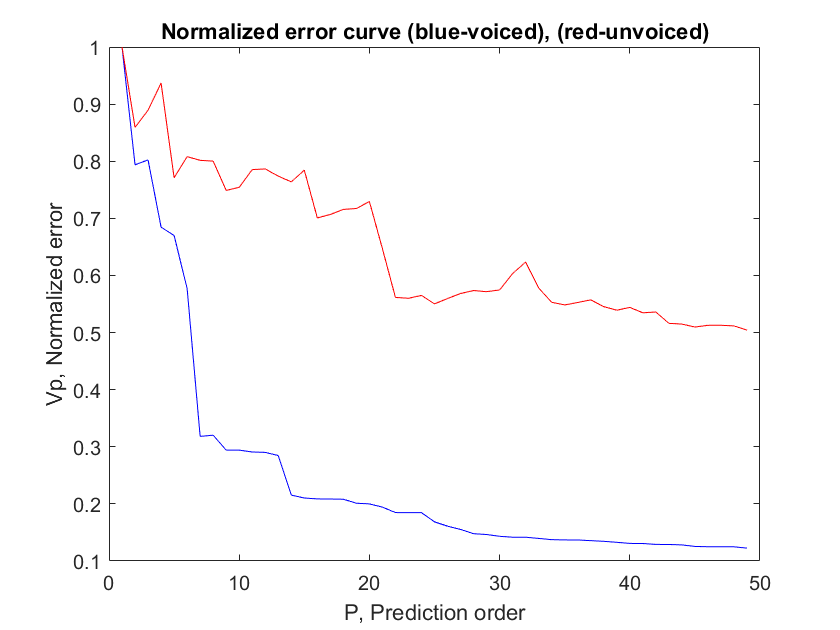

% plotting
plot(V_p_voiced, 'b');
hold on 
plot(V_p_unvoiced, 'r');
xlabel('P, Prediction order');
ylabel('Vp, Normalized error');
title('Normalized error curve (blue-voiced), (red-unvoiced)');

#### 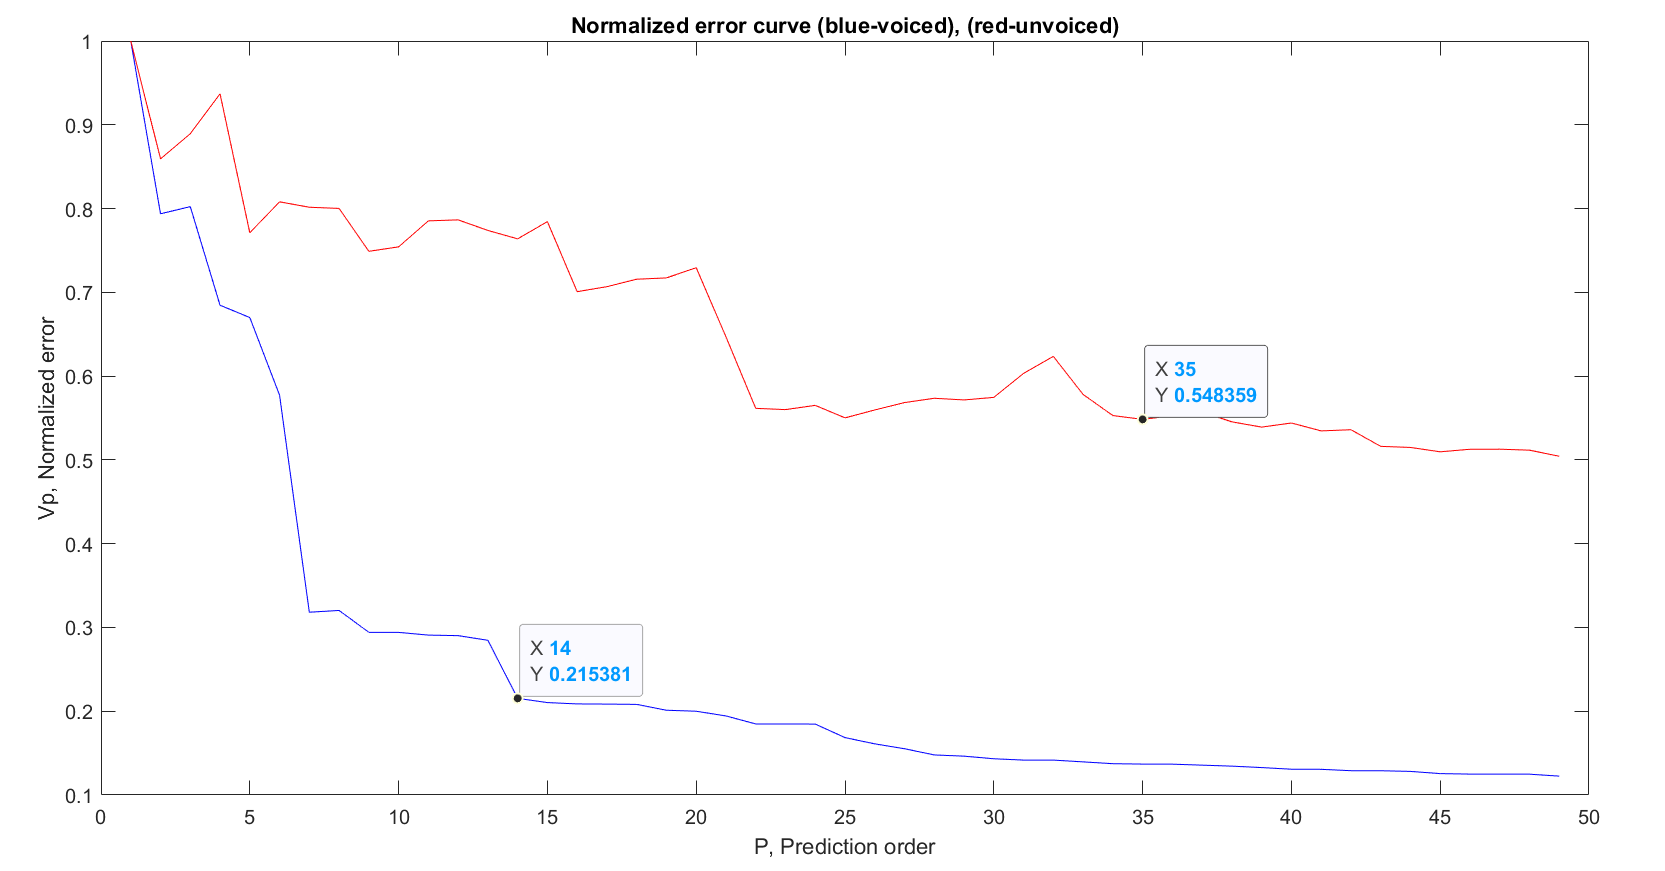

#### **Observations:**

After a certain p value, there is no drastic decrease in the error, so we can take that p value as our optimal order.

### Function Definitions

function plot_time_signal(y, fs, title_name)  % PLOT TIME DOMAIN PLOT FOR ANY SIGNAL
    plot((0:length(y)-1)/fs,y);
    xlabel("Time");
    ylabel("Amplitude");
    title(title_name);
end

function plot_freq_spectrum(x, fs, title_name, mode)
    N = length(x);
    n = pow2(nextpow2(N)); % Transforming the length so that the number of samples is a power of 2. 
    f = fs*[0: n-1]/n;
    if strcmp(mode, 'linear')
        X_mags = (abs(fft(x, n)));
        X_mags = X_mags/n;
        y_label = 'Linear scale magnitude';
    elseif  strcmp(mode, 'log')
        X_mags = 20*log10(abs(fft(x, n)));
        y_label = 'Log scale magnitude (dB)';
    end
    N_2 = ceil(n/2);
    plot(f(1:N_2), (X_mags(1:N_2)));
    xlabel('Frequency (Hz)')
    ylabel(y_label);
    title(title_name);
end

% CALCULATING AUTO CORRELATION FUNCTION
function ACF = autocorr(no_of_samples, signal)
    N = no_of_samples;
    ACF = [];
    for i = 1:N 
        sum = 0;
        for j = 1:N-i
            sum = sum + signal(j)*signal(j+i);
        end
        ACF = [ACF sum];
    end
    ACF = ACF./max(ACF);
end